clear, close all, clc

Datasættet er temperaturer for ringene på en rumraketaffyring.

load('dataset_problem_6_19.mat') %Indlæser datasæt

a) Find stikprøvens gennemsnit og standardafvigelse og lav et prikdiagram over temperaturdataet.

X_hat = mean(X)

X_hat = 65.8611


sum = 0;
for n = 1:length(X)
    sum = sum + (X(n)-X_hat)^2;
    n = n+1;
end
s_sq = sum/(n-2)

s_sq = 147.8373

s = sqrt(s_sq)

s = 12.1588


% FREM FOR FOR-LOOP BRUGES:
s = std(X)

ans = 12.1588

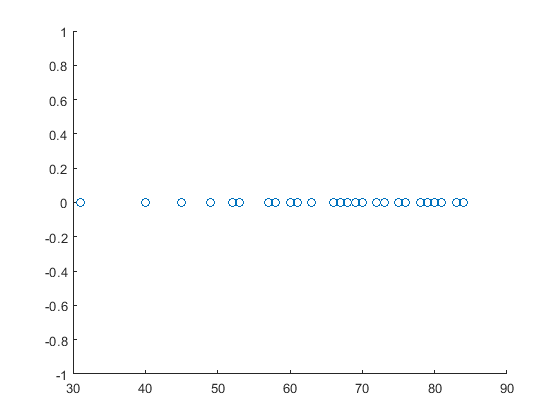


for n = 1:length(X)
    Y(n) = 0;
    n = n+1;
end
scatter(X,Y)

b) Fjern den mindste værdi på 31 og omregn spørgsmål a. Kommenter. Hvor "forskellige" er de andre værdier fra denne sidste værdi?

sum = 0;
for n = 1:length(X)
    if X(n)==31
        n = n+1;
    else
        sum = sum + X(n);
        n = n+1;
    end
end
X_hat = sum/(length(X)-1)

X_hat = 66.8571


sum = 0;
for n = 1:length(X)
    if X(n) == 31
        n = n+1;
    else
        sum = sum + (X(n)-X_hat)^2;
        n = n+1;
    end
end
s_sq = sum/(n-3)

s_sq = 115.4202

s = sqrt(s_sq)

s = 10.7434

Gennemsnittet er steget meget lidt, mens standardafvigelsen er faldet med omkring 15%.